clear;clc;
% This is the original test.
% readpath='I:\GS\Go_abroad\results\CMU\course_research\Research\tangdata\V1_Data\M151023\Site1\train\Pics\';
%
% b1=imread([readpath,'1.bmp']);
% bb1=imresize(b1,[50,50],'cubic');
% k=0.06;% k: experience constant, 0.04-0.06
% __________________________________________
% lambda_all=get_lambda(harrismatrix,det_trace);
% RR=compute_R(lambda_all,k);% 这个方法算出来和上面的R差不多，除了个别精度的问题
% bb1
% [harrismatrix,det_trace,R_all]=Harris1(bb1,0.06)
% R_avg=get_mask_all_R(bb1,R_all,12.5,'dontshowplots')
% k=size(dir([readpath,'*.bmp']),1);
% for i=1:k
% g=dir([readpath,num2str(i),'*.bmp']);
% b{i}=g.name;
% end
% b
%
% for i=1:size(b,2)
%     a1=imread([readpath,b{i}]);
%     a2=imresize(a1,[50,50],'cubic');
%     [~,~,R_all2]=Harris1(a2,0.06);
%     R_avg2(i)=get_mask_all_R(a2,R_all2,12.5,'showplots');
% end
% R_avg2
% % R_all=get_all_R(readpath,b,k,'plot');

% _____________________Data read and calculation_____________________

% ___visualization imgs data's R calculate
% datapath="C:\Users\J\Desktop\tang_results\harrismatrix_test\M2S1_vis_picsdata.mat";
% datamatrix=load(datapath);
% picsdata=datamatrix.matrix;
% R_avg=find_all_R(picsdata);
% % Visualization imgs
% R_avg
% save('C:\Users\J\Desktop\tang_results\harrismatrix_test\R_avg_vis.mat','R_avg')

% ___train imgs data's R calculate
% train_datamatrix=load('C:\Users\J\Desktop\tang_results\harrismatrix_test\M2S1_train_pics.mat');
% traindata=train_datamatrix.matrix;
% R_avg_train=find_all_R(traindata);
% save('C:\Users\J\Desktop\tang_results\harrismatrix_test\R_avg_train.mat','R_avg_train')

% visualization imgs, plots and move files
datav=load("C:\Users\J\Desktop\tang_results\harrismatrix_test\R_avg_vis.mat")

datav = 包含以下字段的 struct :
    R_avg: [1×299 double]


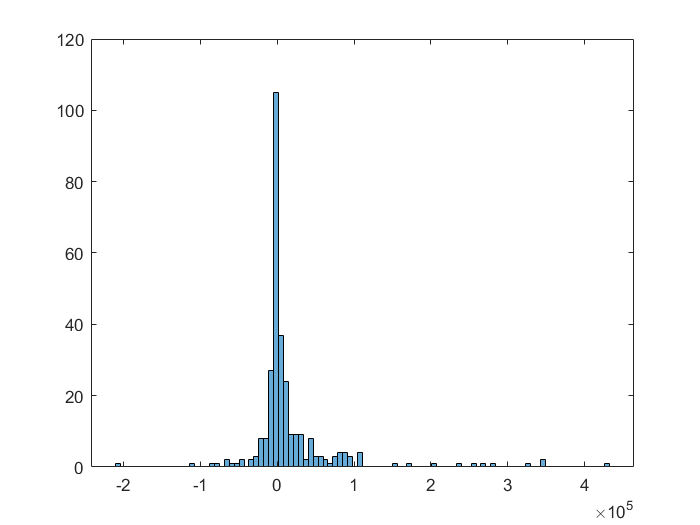

R_avg=datav.R_avg;
histogram(R_avg,100)

readpath='C:\Users\J\Desktop\tang_results\visualization_results_m2s1_modified\visulization_results_m2s1\';
savepath='C:\Users\J\Desktop\tang_results\harrismatrix_test\imgs_1k_5k\';
[index1,index2,index3]=thresholding(R_avg);
mov_directed_file(readpath,savepath,R_avg);

new_path = 'C:\Users\J\Desktop\tang_results\harrismatrix_test\imgs_1k_5k\Bar\'

new_path = 'C:\Users\J\Desktop\tang_results\harrismatrix_test\imgs_1k_5k\uniform\'

new_path = 'C:\Users\J\Desktop\tang_results\harrismatrix_test\imgs_1k_5k\Corner\'

% % train imgs plots and move files
% data=load("C:\Users\J\Desktop\tang_results\harrismatrix_test\R_avg_train.mat")
% R_avg_train=data.R_avg_train
% histogram(R_avg_train,10000)
% readpath='I:\GS\Go_abroad\results\CMU\course_research\Research\tangdata\V1_Data\M151023\Site1\train\Pics\';
% savepath='C:\Users\J\Desktop\tang_results\harrismatrix_test\train_imgs\';
% % [index1,index2,index3]=thresholding(R_avg);

%train move files
% mov_directed_file(readpath,savepath,R_avg_train);

function mov_directed_file(readpath,savepath,R_avg)
[index1,index2,index3]=thresholding(R_avg);
mov_file(index1,readpath,savepath,'Bar')
mov_file(index2,readpath,savepath,'uniform')
mov_file(index3,readpath,savepath,'Corner')
end

function mov_file(index,readpath,savepath,savepathname)
mainpath='C:\Users\J\Desktop\tang_results\harrismatrix_test\';
if exist(savepath)==0
    createfolders(mainpath,'train_imgs');
end
new_path=createfolders(savepath,savepathname)
for i=1:length(index)
    copyfile([readpath,num2str(index(i)),'08.bmp'],new_path); %bmp前缀要改
end


end
function [index1,index2,index3]=thresholding(R_avg)
i1=1000;i2=5000;
index1=find(R_avg<i1);
index2=find(R_avg>i1 & R_avg<i2);
index3=find(R_avg>i2);
end
function path=createfolders(mainpath,folders_names) 
cd(mainpath);mkdir([folders_names,'\']);
path=strcat(mainpath,folders_names,'\');
end

% ____________________________________________________

function R_avg=find_all_R(picsdata)
for i=1:size(picsdata,3)
    pics=picsdata(:,:,i);
    [harrismatrix,det_trace,R_all2]=Harris1(pics,0.06);
    R_avg(i)=get_mask_all_R(pics,R_all2,12.5,'donshowplots');
end
end

function R_avg=get_mask_all_R(img,R,mask_radius,mode)
width = size(img,2);
height = size(img,1);
centerW = width/2;
centerH = height/2;
[W,H] = meshgrid(1:width,1:height);
mask = double(((W-centerW).^2 + (H-centerH).^2) < mask_radius^2);% 这种mask的本质就是设立一个曲面，然后用平面(3维柱体)去切
R_after_mask=R.*mask;
R_all=R_after_mask(logical(mask));
R_avg=mean(R_all);
switch mode
    case 'showplots'
        imshow(uint8(mask.*double(img)))
end
end
% ____________________________________________________

function R=compute_R(lambda_all,k) % 和harris1里面的R差不多，除了个别精度问题
R=cell(size(lambda_all));
for i=1:size(lambda_all,1)
    for j=1:size(lambda_all,2)
        l1=lambda_all{i,j}(1);l2=lambda_all{i,j}(2);
        R{i,j}=l1.*l2-k*(l1+l2).^2;
    end
end
end

function lambda_all=get_lambda(harrismatrix,det_trace)
% lambda_all=zeros(size(det_trace));
lambda_all=cell(size(harrismatrix));
k=1;
for i=1:size(harrismatrix,1)
    for j=1:size(harrismatrix,2)
        harris=harrismatrix{i,j};
        lambda=eig(harris)';
        lambda_all{i,j}=lambda;
        k=k+1;
    end
end
end
% ____________________________________________________


function [harrismatrix,det_trace,R]=Harris1(in_image,a)
arguments
    in_image
    a=0.06
end
% 功能：检测图像harris角点
% in_image-待检测的rgb图像数组
% a--角点参数响应，取值范围：0.04~0.06
% [posr，posc]-角点坐标
% in_image=rgb2gray(in_image);
I=double(in_image);
%%%%计算xy方向梯度%%%%%

fx=[-1,0,1];%x方向梯度模板
Ix=filter2(fx,I);%x方向滤波
fy=[-1;0;1];%y方向梯度模板(注意是分号)
Iy=filter2(fy,I);
%%%%计算两个方向梯度的乘积%%%%%
Ix2=Ix.^2;
Iy2=Iy.^2;
Ixy=Ix.*Iy;
%%%%使用高斯加权函数对梯度乘积进行加权%%%%
%产生一个7*7的高斯窗函数，sigma值为2
h=fspecial('gaussian',[7,7],2);
IX2=filter2(h,Ix2);
IY2=filter2(h,Iy2);
IXY=filter2(h,Ixy);
%%%%%计算每个像元的Harris响应值%%%%%
[height,width]=size(I);
R=zeros(height,width);
%像素(i,j)处的Harris响应值
% det_trace=zeros(height*width,2);
k=1;
for i=1:height
    for j=1:width
        M=[IX2(i,j) IXY(i,j);IXY(i,j) IY2(i,j)];
        R(i,j)=det(M)-a*(trace(M))^2;
        det_trace(k,:)=[det(M) trace(M)];
        k=k+1;
        harrismatrix{i,j}=M;
    end
end


%%%%%去掉小阈值的Harris值%%%%% 这个是把R小的和负的置零
% Rmax=max(max(R));
% %阈值,将R矩阵中，小于特定值的直接扔掉
% t=0.01*Rmax;
% for i=1:height
%     for j=1:width
%         if R(i,j)<t
%             R(i,j)=0;
%         end
%     end
% end


% %%%%%进行3*3领域非极大值抑制%%%%%%%%%这个是画图的
% corner_peaks=imregionalmax(R);% 其实相当于3*3pooling，然后返回当前位置的逻辑值
% %imregionalmax对二维图片，采用8领域（默认，也可指定）查找极值，三维图片采用26领域
% %极值置为1，其余置为0
% num=sum(sum(corner_peaks));
% %%%%%%显示所提取的Harris角点%%%%
% [posr,posc]=find(corner_peaks==1); %posr行index，posc列index
% figure
% imshow(in_image);
% hold on
% for i=1:length(posr)
%     plot(posc(i),posr(i),'r+');
% end
end